# Motor Sequence Learning (MSL) - TMR Experiment

Analysis of the behavioral data

% Ella Gabitov (gabitovella@gmail.com), 15 December 2022

## Init

% Regular text interpreter
set(0,'DefaultTextInterpreter','none')

## Analysis Info

### Data for Analysis

[actfile_dpath, ~, ~] = fileparts(matlab.desktop.editor.getActiveFilename);
[main_dpath, ~, ~] = fileparts(actfile_dpath);

add2path = {...
    fullfile(main_dpath, 'analysis');
    };
for i = 1 : length(add2path)
    addpath(add2path{i});
end

% Path to the directory with data for analysis
% data_dpath = '/Users/prakritigupta/Desktop/My MSL task/Piloting behavioural/Data /Phase 1/Final Seq 13243142/results';
data_dpath = fullfile(main_dpath, 'results');


### Sessions for Analysis

% Sessions for analysis
sessions = {'PreSleep_training', 'PreSleep_test', 'PostSleep_test'};

### Subjects for Analysis

% A list of subjects
% The data of each subject is stored in the directory with the same name as the subject identifier

% Get all subjects from the src directory
list_dir = dir(data_dpath);
subjects = {list_dir([list_dir(:).isdir]).name};
subjects(contains(subjects, '.')) = []; % Should not contain dots

% Specify subjects explicitly
% subjects = {...
%     'Subject1'...
%     'Subject2'...
%     'Subject3'...
%     };


## Individual Plots

% Plot properties
f_size = [2000, 800]; % the width and the height of the figure
font_size = 8;
marker_size = 4;


### Performance Duration

Performance durations are plotted for each block. They are calculated starting from the first input key until the end of the corresponding block.

- Each training block comprises 24 keypresses, equivalent to 3 repetitions of a given 8-element sequence 

- Each test block comprises 80 keypresses, equivalent to 10 repetitions of a given 8-element sequence 

---


P1_01_A01


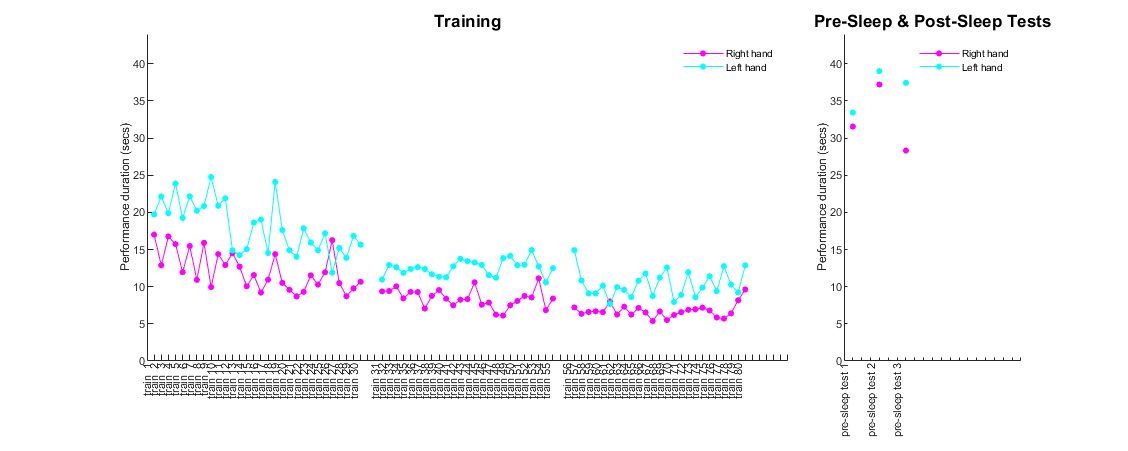

% Y axis properties
measure_desc = 'duration';

for i_subj = 1 : length(subjects)
    subj = subjects{i_subj};
    data_subj_dpath = fullfile(data_dpath, subj);
    disp('---');
    disp(subj);

    plot_subj_data(subj, data_subj_dpath, sessions, measure_desc, f_size, font_size, marker_size);

end

### Mean Inter-Keypress Intervals

Mean inter-key intervals (IKI) are plotted for each block. They are calculated as mean differences between onsets of each pair of consequitive input keys.

- Each training block comprises 24 keypresses, equivalent to 3 repetitions of a given 8-element sequence 

- Each test block comprises 80 keypresses, equivalent to 10 repetitions of a given 8-element sequence 

---


P1_01_A01


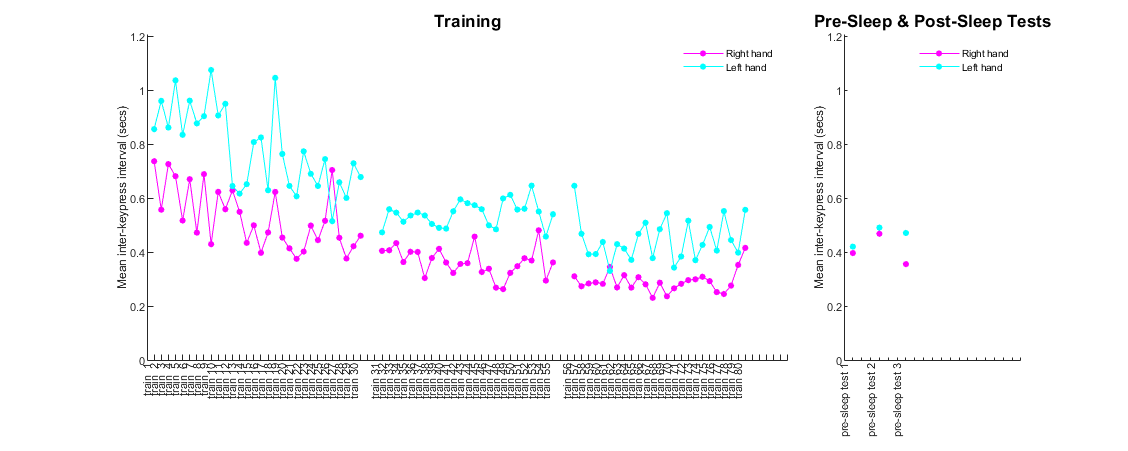

% Y axis properties
measure_desc = 'inter-keypress interval';

for i_subj = 1 : length(subjects)
    subj = subjects{i_subj};
    data_subj_dpath = fullfile(data_dpath, subj);
    disp('---');
    disp(subj);

    plot_subj_data(subj, data_subj_dpath, sessions, measure_desc, f_size, font_size, marker_size);

end

## Clear & Close

% for i = 1 : length(add2path)
%     rmpath(add2path{i});
% end
% 
% clearvars;


## Utils

function plot_subj_data(subj, data_subj_dpath, sessions, measure_desc, f_size, font_size, marker_size)

switch measure_desc
    case 'duration'
        y_label = 'Performance duration (secs)';
    case 'inter-keypress interval'
        y_label = 'Mean inter-keypress interval (secs)';
end

% A new figure with two subplots in a single row
f = figure();
f.Position = [0, 0, f_size];

% 3/4 of the figure to plot the training data
ax_training = subplot(1, 4, 1:3);

% 1/4 of the figure to plot the pre-sleep and post-sleep tests
ax_tests = subplot(1, 4, 4);
init_tests = true;

for i_sess = 1 : length(sessions)
    list_dir = dir(fullfile(data_subj_dpath, [subj, '_', sessions{i_sess}, '*.mat']));
    fnames = {list_dir.name};

    if isempty(fnames)
        continue;
    end

    switch sessions{i_sess}
        case 'PreSleep_training'
            sess_title = 'Training';
            sess_lbl = 'train';

            % Init plot properties for the training session
            ax2plot = ax_training;
            x_lim = [0 90];
            x_ticks = x_lim(1):x_lim(2);
            x_tick_labels = cell(1, length(x_ticks));
            x_tick_labels(:) = {''};
            x_end = 0; % Is used to calculate the next value along the x axis
            right_is_labeled = 0;
            left_is_labeled = 0;

        case 'PreSleep_test'
            sess_title = 'Pre-Sleep & Post-Sleep Tests';
            sess_lbl = 'pre-sleep test';
            
             % Init plot properties for tests
            if init_tests
                ax2plot = ax_tests;
                x_lim = [0 20];
                x_ticks = x_lim(1):x_lim(2);
                x_tick_labels = cell(1, length(x_ticks));
                x_tick_labels(:) = {''};
                x_end = 0; % Is used to calculate the next value along the x axis
                right_is_labeled = 0;
                left_is_labeled = 0;
                init_tests = false;
            end

        case 'PostSleep_test'
            sess_title = 'Pre-Sleep & Post-Sleep Tests';                
            sess_lbl = 'post-sleep test';
             % Init plot properties for tests
            if init_tests
                ax2plot = ax_tests;
                x_lim = [0 20];
                x_ticks = x_lim(1):x_lim(2);
                x_tick_labels = cell(1, length(x_ticks));
                x_tick_labels(:) = {''};
                x_end = 0; % Is used to calculate the next value along the x axis
                right_is_labeled = 0;
                left_is_labeled = 0;
                init_tests = false;
            end
    end % SWITCH

    % Count blocks to plot
    count_blocks = 0;
    for i_fname = 1 : length(fnames)
        src_fpath = fullfile(data_subj_dpath, fnames{i_fname});
        
        % Plot the data
        [x, count_blocks, x_tick_labels, right_is_labeled, left_is_labeled] = plot_data(...
            src_fpath, sess_lbl, measure_desc,...
            x_end, count_blocks,...
            ax2plot, x_tick_labels, right_is_labeled, left_is_labeled, marker_size);

        % Add gap before plotting the data for the next phase of the current session
        x_end = x_end + length(x) + 2;
    end

    % Set plot properties
    subplot(ax2plot);
    set(gca, 'box', 'off');
    ax2plot.FontSize = font_size;
    ax2plot.Title.String = sess_title;
    ax2plot.Title.FontSize = font_size * 1.6;
    ax2plot.XLim = x_lim;
    ax2plot.XTick = x_ticks;
    ax2plot.XTickLabel = x_tick_labels;
    ax2plot.XTickLabelRotation = 90;
    ax2plot.YLabel.String = y_label;

    % Add gap before plotting the data for the next session
    x_end = x_end + 4;

end

% Align y-axes of the plots
y_max = max([ax_training.YLim(:); ax_tests.YLim(:)])*1.1;
ax_training.YLim = [0, y_max];
ax_tests.YLim = [0, y_max];

% Align x-axes of the plots and adjust their heights
ax_training.Position([2, 4]) = [0.2, sum(ax_training.Position([2, 4]))-0.2];
ax_tests.Position([2, 4]) = [0.2, sum(ax_tests.Position([2, 4]))-0.2];

hold off;

end


function [x, count_blocks, x_tick_labels, right_is_labeled, left_is_labeled] = plot_data(...
    src_fpath, sess_lbl, measure_desc,...
    x_end, count_blocks,...
    ax2plot, x_tick_labels, right_is_labeled, left_is_labeled, marker_size)
    
% Load the data
data_loaded = load(src_fpath);
blocks_info = data_loaded.blocks.info;
input_onsets = data_loaded.blocks.input_onsets;

switch measure_desc
    case 'duration'
        measure = input_onsets(:, end) - input_onsets(:, 1);
    case 'inter-keypress interval'
        measure = mean(diff(input_onsets, 1, 2), 2);
end

is_right = strcmp(blocks_info.hand, 'right');
is_left = strcmp(blocks_info.hand, 'left');

x = x_end+1 : x_end+max(sum(is_right), sum(is_left));
labels = cellstr(strcat(sess_lbl, {' '}, num2str((count_blocks+1 : count_blocks+length(x))')));
count_blocks = count_blocks+length(x);
x_tick_labels(x) = labels;

subplot(ax2plot);

% --- PLOT DATA FOR THE RIGHT HAND

% Magenta color - circle markers - dashed line
plot_str = 'm o -';
marker_face_color = 'm';

y_plot = measure(is_right);
x_plot = x(1:length(y_plot));
% Add to plot and add the hand label if needed
if right_is_labeled
    p = plot(x_plot, y_plot, plot_str, 'MarkerSize', marker_size, 'HandleVisibility', 'off');
else
    p = plot(x_plot, y_plot, plot_str, 'MarkerSize', marker_size, 'DisplayName', 'Right hand');
    right_is_labeled = 1;
end
p.MarkerFaceColor = marker_face_color;
hold on;

% --- PLOT DATA FOR THE LEFT HAND

% Cyan color - circle markers - dashed line
plot_str = 'c o -'; 
marker_face_color = 'c';

y_plot = measure(is_left);
x_plot = x(1:length(y_plot));            

% Add to plot and add the hand label if needed
if left_is_labeled
    p = plot(x_plot, y_plot, plot_str, 'MarkerSize', marker_size, 'HandleVisibility', 'off');
else
    p = plot(x_plot, y_plot, plot_str, 'MarkerSize', marker_size, 'DisplayName', 'Left hand');
    left_is_labeled = 1;
end
p.MarkerFaceColor = marker_face_color;

legend boxoff;
legend('show');
drawnow;
hold on;

end
